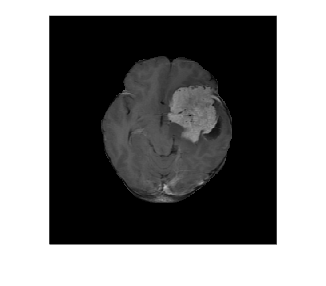

close all
clear all
clc

I = imgetfile();
Io = imread(I);
figure, imshow(Io), title('Original Image');


%%Add noise to image
I_noised = Inoised(Io);
noised = uint8(I_noised);
figure, imshow(mat2gray(I_noised)), title('Noised Image');
% I_noised = imread('mdb209_noisy_pec.pgm');
% noised=uint8(I_noised);
[psnr1, snr1] = psnr(noised, Io);
psnr1

## PreProcess

preprocessed = preprocess(I_noised);

Unrecognized function or variable 'I_noised'.

preprocess = uint8(preprocessed);
figure, imshow(mat2gray(preprocessed)), title('preProcesed Image');

## Wavelet denoising

denoisedImage = denoise_1(preprocessed);
denoised = uint8(denoisedImage);
figure, imshow(mat2gray(denoisedImage)), title('Wavelet Transformation');

[psnr2, snr2] = psnr(denoised, preprocess);

## Guided filter

Ismooth = imguidedfilter(denoisedImage);
%Ismooth = imdiffusefilt(denoisedImage);
I_smooth = uint8(Ismooth);
figure,imshow(mat2gray(Ismooth)),title('Guided Image');
[psnr3, snr3] = psnr(I_smooth, preprocess);
psnr2
psnr3
% figure, imhist(Ismooth) %chon nguong
% figure,imshow(im2bw(Ismooth,225/255))
%%Crop Image
% crop_I = cropI(Ismooth);
% figure,imshow(crop_I),title('Crop Image');

%MATLAB TOT Denoise image using deep neural network
% net = denoisingNetwork('DnCNN');
% denoisedI = denoiseImage(preprocessed,net);
% figure,mshow(denoisedI)
%%%%%%%%%%%
%khu nhieu bang Ma

[h0 k0]= imhist(Io);
[h1 k1]= imhist(I_noised);
[h2 k2]= imhist(uint8(IMDEN));
Begin_Cut_Position = 30;
End_Cut_Position = 100;

Smooth_h0 = smooth(smooth(h0(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h0 = Smooth_h0/max(Smooth_h0(:)); % Chuan Hoa OI Image

Smooth_h1 = smooth(smooth(h1(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h1 = Smooth_h1/max(Smooth_h1(:)); % Chuan Hoa Noisy Image

Smooth_h2 = smooth(smooth(h2(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h2 = Smooth_h2/max(Smooth_h2(:)); % Chuan Hoa PDF Cua Denoise Image

figure(14);
plot(k0(Begin_Cut_Position : end - End_Cut_Position),Smooth_h0,'k');
hold on;
plot(k1(Begin_Cut_Position : end - End_Cut_Position),Smooth_h1,'k-.');
hold on;
plot(k2(Begin_Cut_Position : end - End_Cut_Position),Smooth_h2,'k.');
hold off;
legend('OI Image','Noisy Image','Denoise Enhancement Image')
[h0 k0]= imhist(Io);
[h1 k1]= imhist(I_noised);
[h2 k2]= imhist(uint8(IMDEN));
Begin_Cut_Position = 30;
End_Cut_Position = 100;

Smooth_h0 = smooth(smooth(h0(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h0 = Smooth_h0/max(Smooth_h0(:)); % Chuan Hoa OI Image

Smooth_h1 = smooth(smooth(h1(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h1 = Smooth_h1/max(Smooth_h1(:)); % Chuan Hoa Noisy Image

Smooth_h2 = smooth(smooth(h2(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h2 = Smooth_h2/max(Smooth_h2(:)); % Chuan Hoa PDF Cua Denoise Image

figure(14);
plot(k0(Begin_Cut_Position : end - End_Cut_Position),Smooth_h0,'k');
hold on;
plot(k1(Begin_Cut_Position : end - End_Cut_Position),Smooth_h1,'k-.');
hold on;
plot(k2(Begin_Cut_Position : end - End_Cut_Position),Smooth_h2,'k.');
hold off;
legend('OI Image','Noisy Image','Denoise Enhancement Image')


%Ve PDF
[h0 k0]= imhist(Io);
[h1 k1]= imhist(I_noised);
[h2 k2]= imhist(uint8(IMDEN));
Begin_Cut_Position = 30;
End_Cut_Position = 100;

Smooth_h0 = smooth(smooth(h0(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h0 = Smooth_h0/max(Smooth_h0(:)); % Chuan Hoa OI Image

Smooth_h1 = smooth(smooth(h1(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h1 = Smooth_h1/max(Smooth_h1(:)); % Chuan Hoa Noisy Image

Smooth_h2 = smooth(smooth(h2(Begin_Cut_Position : end - End_Cut_Position)));
Smooth_h2 = Smooth_h2/max(Smooth_h2(:)); % Chuan Hoa PDF Cua Denoise Image

figure(14);
plot(k0(Begin_Cut_Position : end - End_Cut_Position),Smooth_h0,'k');
hold on;
plot(k1(Begin_Cut_Position : end - End_Cut_Position),Smooth_h1,'k-.');
hold on;
plot(k2(Begin_Cut_Position : end - End_Cut_Position),Smooth_h2,'k.');
hold off;
legend('OI Image','Noisy Image','Denoise Enhancement Image')